# Building automation case study

**Case study: Model with large number of continuous variables**

Author: Birgit van Huijgevoort

[@Birgit, add a description of what this script is about, e.g., what specification you are trying to satisfy, etc.]

#### Initialization

clc; clear; close all;

% Add toolboxes to path
run Install.m

Please add either tensortoolbox or tensor lab to your path
 You can download the tensortoolbox for matlab from  https://www.tensortoolbox.org
MPT toolbox is not automatically installed
Yalmip and Mosek are not automatically installed


% Track runtime
tStart = tic;

## Specify parameters of 7-dimensional model

#### 7D model by Nathalie Cauchi

sysLTI --> original model 

sysLTIr --> reduced order model

---------------------------

x_c[k+1] = A_cx_c[k] + B_cu_c[k] + F_cd_c[k] + Q_c 

y_c[k] = [1 0 0 0 0 0 0] 

x_c = [T_z1 T_z2 T_w5 T_w6 T_w2 T_w3 T_w7]^T 

u_c = T_sa 

d_c = [T_out T_hall CO2_1 CO2_2 T_rw r1 T_rw r2]^T 

% Load parameters needed to build model
BASmodel = load('BASmodel.mat');
Z1m = BASmodel.Z1m;
Qc = BASmodel.Qc;

% Dynamics
A = Z1m.A;
B = Z1m.B;
C = Z1m.C;
D = zeros(1,1);
Bw = Z1m.F(:,1:6);
dim = Z1m.dim;

% Disturbance
mu = [9; 15; 500; 500; 35; 35]; % mean
sigma = ... % variance
    [1, zeros(1,5); ...
    0, 1, zeros(1,4); ...
    0, 0, 100, zeros(1,3); ...
    0, 0, 0, 100, zeros(1,2); ...
    zeros(1,4), 5, 0; ...
    zeros(1,5), 5];

### Transform model such that w comes from Gaussian distribution with mean 0 and unit variance

Bw = Bw * sigma^(1/2);
Qc = Qc + Bw*mu;
mu = zeros(6, 1);
sigma = eye(6);

### Compute bounds on state and input

% Input bounds
ul = 15;
uu = 30;

% Remark:
% Since we have an affine system, we can convert it to a LTI system by
% shifting the state to the steady state. We compensate for this
% afterwards. % [@Birgit, elaborate on how we compensate for this.]

% Define LTI system centered around steady-state point
% Work with system with state x-xss and output y-C*xss
sysLTI = LinModel(A,B,C,D,Bw,mu,sigma);

% Remove Qc by looking at steady state solution
uss = (uu-ul)/2+ul;
uss = 15; % [@Birgit, add some comments to clarify why you hardcode this.]
xss = -inv(A-eye(dim))*(B*uss+Qc);

% New bounds on input space (u-uss) % [@Birgit, why is the input space (potentially) restricted?]
ul = ul-uss;     % Lowerbound input u
uu = uu-uss;     % Upperbound input u
sysLTI.U = Polyhedron(combvec([ul(1),uu(1)])');
% Specify division of input space for actuation and feedback
% [@Birgit, add some comments to clarify]
ula = -0.6*((uu-ul)/2)+((uu-ul)/2)+ul;   % part of input for actuation R*uhat, with R=1
uua = 0.6*((uu-ul)/2)+((uu-ul)/2)+ul;
ulf = -0.175*((uu-ul)/2);   % part of input for feedback K(x-P*xhat)
uuf = 0.175*((uu-ul)/2);

% New bounds on state space (x-xss)
x1l = 19.5-xss(1);   % Lowerbound x1
x1u = 20.5-xss(1);   % Upperbound x1
x2l = 19-xss(2);   % Lowerbound x2
x2u = 22-xss(2);   % Upperbound x2
x3l = 18-xss(3);   % Lowerbound x3
x3u = 22-xss(3);   % Upperbound x3
x4l = 18-xss(4);   % Lowerbound x4
x4u = 22-xss(4);   % Upperbound x4
x5l = 18-xss(5);   % Lowerbound x5
x5u = 22-xss(5);   % Upperbound x5
x6l = 18-xss(6);   % Lowerbound x6
x6u = 22-xss(6);   % Upperbound x6
x7l = 18-xss(7);   % Lowerbound x7
x7u = 22-xss(7);   % Upperbound x7
Xbound = [x1l, x1u; x2l, x2u; x3l, x3u; x4l, x4u; x5l, x5u; x6l, x6u; x7l x7u];
sysLTI.X = Polyhedron(combvec([x1l,x1u],[x2l,x2u],[x3l,x3u],[x4l,x4u],[x5l,x5u],[x6l,x6u],[x7l,x7u])');

### Specify regions for the specification

P1 = sysLTI.X;
P1 = Polyhedron(combvec([x1l,x1u],[-100,100],[-100,100],[-100,100],[-100,100],[-100,100],[-100,100])');

## Reduced order model

Since computing the controller for the 7D model is computationally very intensive, we resort to using a reduced order model instead. We find the reduced order model using balanced truncations on a closed loop system.

f = 0.098; % Constant used for feedback
dimr = 2; % Dimension of reduced order model (currently only working for 2D)
 
[sysLTIr,F] = ModelReduction(sysLTI,dimr,f);

Reduced order model obtained.


% Make sure that the reduced model has first state as output (C = [1 0]) 
% [@Birgit, add some comments to  why this is done]
if sysLTIr.C(1) ~= 1
    % flip outputs
    T2 = [0 1; 1 0];
    
    % set first element to 1
    T = eye(length(sysLTIr.C));
    T(length(sysLTIr.C),length(sysLTIr.C)) = sysLTIr.C(end);
    
    % state transformation
    sysLTIr.A = T2*T*sysLTIr.A*inv(T)*inv(T2);
    sysLTIr.C = sysLTIr.C*inv(T)*inv(T2);
    BBw = T2*T*[sysLTIr.B, sysLTIr.Bw];
    sysLTIr.B = BBw(:,1);
    sysLTIr.Bw = BBw(:,2:end);
end

% Compute P and Q
% [@Birgit, P, Q, R are the matrices used for projecting states of sysLTIr to states of sysLTI?]
[P, Q, R] = ComputeProjection(sysLTI,sysLTIr);

% Bounds on state space [@Birgit, of what?]
x1l = x1l;   % Lowerbound x1
x1u = x1u;   % Upperbound x1

% Compute state space bounds of reduced-order model
Ax = [];
bx = [];
for i = 1:2^dim
    xv = sysLTI.X.V(i,:)';
    for j = 1:dim
        if P(j,2)>=0
            Axi(2*(j-1)+1,:) = [0 -P(j,2)];
            Axi(2*j,:) = [P(j,2) 0];
            bxi(2*(j-1)+1,1) = [-xv(j)+P(j,1)*x1u];
            bxi(2*j,1) = [xv(j)-P(j,1)*x1l];
        else
            Axi(2*(j-1)+1,:) = [0 P(j,2)];
            Axi(2*j,:) = [-P(j,2) 0];
            bxi(2*(j-1)+1,1) = [xv(j)-P(j,1)*x1u];
            bxi(2*j,1) = [-xv(j)+P(j,1)*x1l];
        end
    end
    Ax = [Ax; Axi];
    bx = [bx; bxi];
end

xhatBound = linprog([-1;1], Ax,bx);
if ~isempty(xhatBound)
    x2l = xhatBound(1);   
    x2u = xhatBound(2);   
end

sysLTIr.X = Polyhedron(combvec([x1l,x1u],[x2l,x2u])');

% The input space stays the same
sysLTIr.U = sysLTI.U;

## Specify output region

Specify regions for the specification

TSP = 20-xss(1);               % temperature set point
p1x = [19.5-xss(1) 20.5-xss(1)  20.5-xss(1) 19.5-xss(1) 19.5-xss(1)];    % x1-coordinates
p1y = [-100 -100 100 100 -100];    % x2-coordinates
p1 = [p1x; p1y];        % goal region
P1r = Polyhedron(p1x(1:2)');

sysLTIr.regions = [P1r]; % regions that get specific atomic propositions
sysLTIr.AP = {'p1'}; % with the corresponding atomic propositions

## Synthesize scLTL formula (or input DFA yourself)

N = 6; % Horizon
formula = '(p1 & X p1 & X X p1 & X X X p1 & X X X X p1 & X X X X X p1)';
[DFA] = TranslateSpec(formula, sysLTIr.AP);

never { /* (p1 && X p1 && X X p1 && X X X p1 && X X X X p1 && X X X X X p1) */
accept_init:
	if
	:: (p1) -> goto accept_S2
	fi;
accept_S2:
	if
	:: (p1) -> goto accept_S3
	fi;
accept_S3:
	if
	:: (p1) -> goto accept_S4
	fi;
accept_S4:
	if
	:: (p1) -> goto accept_S5
	fi;
accept_S5:
	if
	:: (p1) -> goto accept_S6
	fi;
accept_S6:
	if
	:: (p1) -> goto accept_all
	fi;
accept_all:
	skip
}

add state
add state
add state
add state
add state
add state


## Reduce state space

[@Birgit, add some comments to clarify what is done here. E.g., why do we have to further reduce the state space if we're already using a reduced order model...]

[~, output_set] = IncreaseDecreasePolytope(P1r, 0.1);
[sysLTIr,~] = ReduceX(sysLTIr, [ula(1),uua(1)], output_set, 'invariance', 5);

Polyhedron in R^2 with representations:
    H-rep               : Unknown (call computeHRep() to compute)
    V-rep (irredundant) : Vertices   4 | Rays   0
Functions : none


## Construct abstract model by gridding it

disp('Start gridding...'); tic

Start gridding...


lu = 3; % Cellwidth for control input
uhat = combvec(linspace(ula(1),uua(1),lu));

l = [3000*3000];  % number of grid cells in x1- and x2-direction
tol = 10^-6;
sysAbs = Gridding(sysLTIr,uhat,l,tol,'TensorComputation',true);
l = sysAbs.l; % load updated l
% Save some extra system parameters into struct
sysAbs.orig = sysLTIr;

% Label state space
label = zeros(1,prod(l));
[label(1:prod(l))] = deal(1);
inP1 = inpolygon(sysAbs.states(1,:),sysAbs.states(2,:),p1x,p1y);
[label(inP1)] = deal(2);
sysAbs.labels = label;
disp(['---> finished gridding in ', num2str(toc), ' seconds.'])

---> finished gridding in 6.6931 seconds.


## Compute delta based on epsilon

% Compute polytope 
beta = sysAbs.beta;
Uhat = Polyhedron(sysAbs.inputs');

% [@Birgit, bounding disturbance at tripple std?]
Wlb = sysLTIr.mu-3*sum(sysLTIr.sigma,2);
Wub = sysLTIr.mu+3*sum(sysLTIr.sigma,2);
Wset = Polyhedron('lb', Wlb, 'ub', Wub);

% Compute additional error, by truncating the disturbance
% [@Birgit, is this a common method?]
onemindel = mvncdf(Wlb,Wub,mu,sigma);
del_trunc = 1-onemindel;

% [@Birgit, add some comments to clarify]
Z = (sysLTI.B*R-P*sysLTIr.B)*Uhat+(sysLTI.Bw-P*sysLTIr.Bw)*Wset;
Zred = Z;
Zred = Z.minVRep();

% [OPTIONAL] This function computes the bounds for epsilon (takes a lot of time)
% epsilonBounds = [eps_max,eps_min]
% [epsilonBounds] = ComputeEpsilonBoundsMOR(sysLTI,sysLTIr,mu,sigma,uuf,Zred,P)
epsilonBounds = [0.2413, 0.0520]; 
eps_l = epsilonBounds(2); eps_u = epsilonBounds(1);

% Pick epsilon
epsilon_1 = 0.2413;
 

% Validate chosen epsilon is feasible
if epsilon_1>=epsilonBounds(2) && epsilon_1<=epsilonBounds(1)
    disp('Feasible epsilon chosen.')
elseif epsilon_1>epsilonBounds(1)
    disp('Epsilon is larger then necessary.')
elseif epsilon_1<=epsilonBounds(2)
    disp('Infeasible epsilon chosen.')
end

Feasible epsilon chosen.


### Two staged simulation relation

disp('Start computing simulation relation...');tic

Start computing simulation relation...



% 1) Compute MOR simulation relation
[delta_1, D_1, K_1, F_1] = ComputeDelta_intPQRK(epsilon_1,sysLTI,sysLTIr,mu,sigma,uuf,Zred,P);
del = delta_1;
delta_1 = delta_1+del_trunc;

% 2) Compute gridding simulation relation
epsilon_2 = max(0.35-epsilon_1,0);
[delta_2, D_2, K_2] = ComputeDelta(epsilon_2,sysLTIr,sysLTIr.mu,sysLTIr.sigma,beta);

delta = delta_1+delta_2;
epsilon = epsilon_1+epsilon_2;

rel_1 = SimRel(epsilon_1,delta_1,D_1);
rel_2 = SimRel(epsilon_2,delta_2,D_2);
rel = rel_1.Combine(rel_2,sysLTIr.X);
disp(['delta = ', num2str(rel.delta), ', epsilon = ', num2str(rel.epsilon) ])

delta = 0.01609, epsilon = 0.35


disp(['---> finished computing simulation relation in ', num2str(toc), ' seconds.'])

---> finished computing simulation relation in 39.4135 seconds.


rel.NonDetLabels  = NonDeterministicLabelling(sysAbs.outputs, sysLTIr.regions, rel);

## Synthesize controller

disp('Start Value iteration...')

Start Value iteration...


[V,pol]  = SynthesizeRobustController(sysAbs,DFA,rel,N,false);

 <---- Start computing robust policy 
Elapsed time is 51.828003 seconds.
Convergence reached!
Number of iteration required, k=2
Elapsed time is 84.381156 seconds.
 ----> Finished computing robust policy in 115.4969


q = DFA.S0;
% Fix Value at initial q0 based on labeling
for i = 1:size(sysAbs.labels,2)
    if sysAbs.labels(i) == 2
        V(q,i) = V(q,i);
    else
        V(q,i) = 0;
    end
end

% Determine computation time
tEnd = toc(tStart);

X1 = reshape(sysAbs.states(1,:),l)+xss(1);
X2 = reshape(sysAbs.states(2,:),l)+xss(2);

VC = reshape(V(q,:),l);

## Plot satisfaction probability

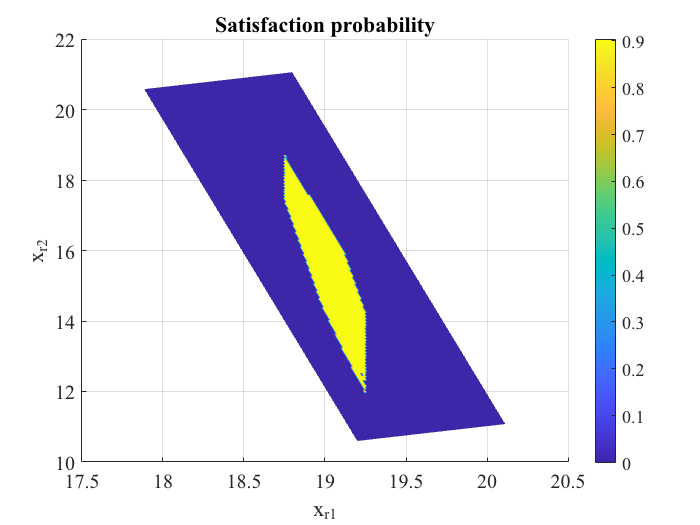

figure;
surf(X1(1:15:end,1:15:end),X2(1:15:end,1:15:end),VC(1:15:end,1:15:end),'EdgeColor','interp')
xlabel('x_{r1}', 'FontSize', 16)
ylabel('x_{r2}', 'FontSize', 16)
zlabel('Satisfaction probability', 'FontSize', 16)
view(2)
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',16)
title("Satisfaction probability")
colorbar

## Start simulation

YSIM = [];
USIM = [];
[i,j] = max(V(DFA.S0,:));
xr0 = sysAbs.states(:,j);
x0 = P*xr0;

% Run the simulation 6 times
for l = 1:6 
    xsim = [x0];
    xrsim = [xr0];

    q = DFA.S0;
        if P1r.contains(sysLTIr.C*xr0)
            label = 2;
        else
            label = 1;
        end
    q_next = DFA.trans(q,label);

    % Find initial abstract state, look at xr0
    diff = abs(xr0.*ones(1,size(sysAbs.states,2))-sysAbs.states);
    dis = sqrt(sum(diff.^2,1));
    [~,j] = min(dis);

    xhat0 = sysAbs.states(:,j);
    xhatsim = [xhat0];

    % Satisfaction probability of this initial state
    SatProp = V(q,j);
    disp(['Value function at x0 equals ', mat2str(SatProp,4),])

    uhat = pol(:,j, q_next);
    indexing = 1:length(sysAbs.states);

    ursim = [];
    usim = [];
    q = q_next;
    for i = 1:N
        disp(['x = ', mat2str(xsim(:,i)+xss,4), ',    q^+ = ',num2str(q_next)])    % compute next continuous state

        if q ==DFA.F
            disp("satisfied specification")
            break;
        elseif q == DFA.sink
            disp("failed specification")
            break;
        end
        w = mvnrnd(sysLTIr.mu,sysLTIr.sigma)';

        u = R*uhat + Q*xrsim(:,i) + K_1*(xsim(:,i)-P*xrsim(:,i));
        ur = uhat;
        ursim = [ursim, ur];
        usim = [usim, u];

        xnext = sysLTI.A*xsim(:,i)+sysLTI.B*u+sysLTI.Bw*w;
        xsim = [xsim, xnext];

        wr = w+F_1*(xsim(:,i)-P*xrsim(:,i));
        xrnext = sysLTIr.A*xrsim(:,i)+sysLTIr.B*ur+sysLTIr.Bw*wr;
        xrsim = [xrsim, xrnext];

        if P1.contains(xsim(:,end)) 
            label = 2;
        elseif xsim(1,end)>=19.5-xss(1) && xsim(1,end)<=20.5-xss(1)
            label = 2;
        else
            label = 1;
        end
        q_next = DFA.trans(q,label);

        % Find next abstract state, by looking at the maximizer in R wrt the value
        % function. 

        diff2 = abs(xrsim(:,end).*ones(1,size(sysAbs.states,2))-sysAbs.states);
        inR2 = (([1 1]*((D_2^.5*diff2).^2)).^.5)<=epsilon_2;
        inR = inR2;
        indices_valid = indexing(inR);
        V_q = V(q_next,:);
        [value_max, index_aux] = max(V_q(inR));
        j = indices_valid(index_aux); % find maximizing index of abstract state
        xhatnext = sysAbs.states(:,j);
        xhatsim = [xhatsim, xhatnext];

        uhat = [pol(:,j,q_next)];

        q = q_next;
    end
    
    % compute output
    y = C*xsim+C*xss;
    usim_ss = usim+uss;
    
    YSIM = [YSIM; y];
    USIM = [USIM; usim_ss];
end

Value function at x0 equals 0.9035


x = [20.5;18.89;9.177;9.67;10.85;11.7;9.741],    q^+ = 4
x = [20.13;18.6;9.838;10.13;11.45;12.1;10.76],    q^+ = 5
x = [19.95;18.46;10.41;10.53;12.02;12.5;11.64],    q^+ = 6
x = [19.91;18.43;10.99;10.95;12.57;12.89;12.42],    q^+ = 7
x = [19.96;18.49;11.37;11.21;13.07;13.25;13.12],    q^+ = 8
x = [20.04;18.55;11.88;11.59;13.47;13.53;13.74],    q^+ = 1


satisfied specification


Value function at x0 equals 0.9035


x = [20.5;18.89;9.177;9.67;10.85;11.7;9.741],    q^+ = 4
x = [20.13;18.62;9.916;10.2;11.51;12.16;10.76],    q^+ = 5
x = [19.97;18.52;10.5;10.62;12.1;12.57;11.65],    q^+ = 6
x = [19.91;18.49;11.04;11;12.65;12.97;12.43],    q^+ = 7
x = [19.95;18.5;11.6;11.42;13.14;13.33;13.12],    q^+ = 8
x = [20.06;18.58;12.02;11.73;13.55;13.61;13.75],    q^+ = 1


satisfied specification


Value function at x0 equals 0.9035


x = [20.5;18.89;9.177;9.67;10.85;11.7;9.741],    q^+ = 4
x = [20.13;18.62;9.778;10.08;11.55;12.19;10.76],    q^+ = 5
x = [19.94;18.48;10.35;10.47;12.17;12.64;11.65],    q^+ = 6
x = [19.9;18.45;10.92;10.89;12.7;13.02;12.42],    q^+ = 7
x = [19.94;18.47;11.36;11.2;13.2;13.38;13.12],    q^+ = 8
x = [20.01;18.54;11.77;11.49;13.59;13.65;13.74],    q^+ = 1


satisfied specification


Value function at x0 equals 0.9035


x = [20.5;18.89;9.177;9.67;10.85;11.7;9.741],    q^+ = 4
x = [20.12;18.6;9.908;10.2;11.51;12.16;10.76],    q^+ = 5
x = [19.94;18.48;10.56;10.67;12.09;12.56;11.64],    q^+ = 6
x = [19.91;18.46;11.02;10.99;12.63;12.95;12.42],    q^+ = 7
x = [19.97;18.5;11.49;11.32;13.09;13.28;13.12],    q^+ = 8
x = [20.07;18.57;11.97;11.68;13.59;13.65;13.75],    q^+ = 1


satisfied specification


Value function at x0 equals 0.9035


x = [20.5;18.89;9.177;9.67;10.85;11.7;9.741],    q^+ = 4
x = [20.14;18.61;9.899;10.19;11.57;12.21;10.76],    q^+ = 5
x = [19.97;18.48;10.53;10.64;12.11;12.58;11.65],    q^+ = 6
x = [19.93;18.45;11.01;10.97;12.66;12.98;12.42],    q^+ = 7
x = [19.97;18.5;11.5;11.33;13.21;13.38;13.12],    q^+ = 8
x = [20.08;18.58;11.93;11.64;13.68;13.73;13.75],    q^+ = 1


satisfied specification


Value function at x0 equals 0.9035


x = [20.5;18.89;9.177;9.67;10.85;11.7;9.741],    q^+ = 4
x = [20.12;18.63;9.908;10.2;11.51;12.15;10.76],    q^+ = 5
x = [19.95;18.49;10.57;10.68;12.02;12.5;11.65],    q^+ = 6
x = [19.91;18.46;11.17;11.12;12.62;12.94;12.42],    q^+ = 7
x = [19.96;18.49;11.65;11.47;13.1;13.28;13.12],    q^+ = 8
x = [20.05;18.57;12.07;11.77;13.54;13.61;13.75],    q^+ = 1


satisfied specification


## Plot results

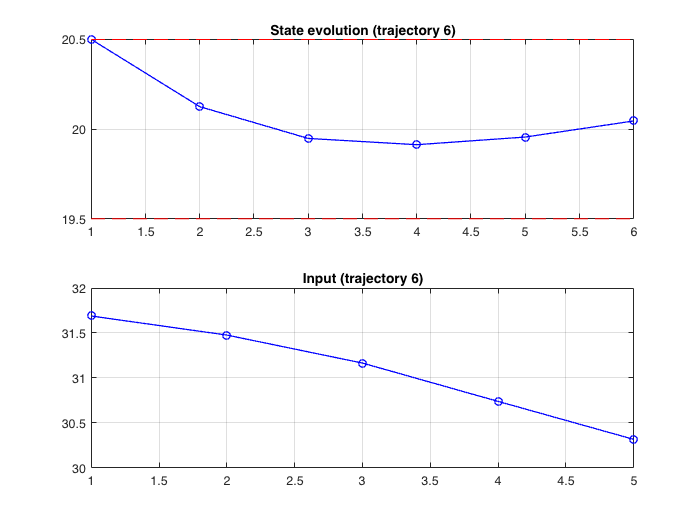

figure;
subplot(2,1,1)
plot(y(1,:), 'bo-', 'LineWidth', 1)
hold on
plot(1:N,19.5*ones(1,N),'r--')
plot(1:N,20.5*ones(1,N),'r--')
title('State evolution (trajectory 6)')
grid on

subplot(2,1,2)
plot(usim+uss, 'bo-', 'LineWidth', 1);
title('Input (trajectory 6)')
grid on

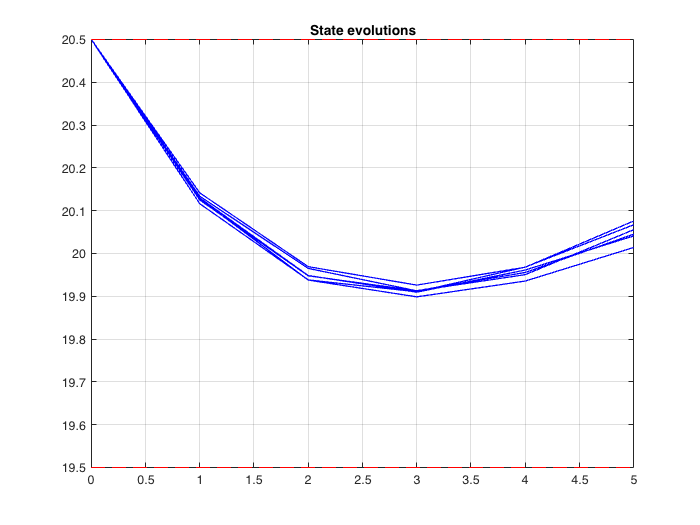

k = 0:5;
figure;
plot(k, YSIM', 'b-', 'LineWidth', 1)
hold on
plot(0:N-1,19.5*ones(1,N),'r--')
plot(0:N-1,20.5*ones(1,N),'r--')
title('State evolutions')
grid on

## Display execution time

end time is before simulation part

tEnd = toc;
disp(['Total runtime = ', mat2str(tEnd), ' seconds'])

Total runtime = 144.497397042 seconds


## Verify input bound

% [@Birgit, add some comments to clarify what this section is about]
Qx = Q*sysLTIr.X;
Qx = Qx.minVRep();

u_lb = ula+ulf+min(Qx.V);
u_ub = uua+uuf+max(Qx.V);

% Use only (abstract) states with V>0
[~,j] = find(V(DFA.S0,:)>0);
XX = sysAbs.states(:,j);

u_lb2 = ula+ulf+min(Q*XX);
u_ub2 = uua+uuf+max(Q*XX);

disp(['Input is between ', mat2str(u_lb2+uss,4), ' and ', mat2str(u_ub2+uss,4)])

Input is between 17.67 and 33.08
